# **TRATAMIENTO DIGITAL DE IMAGENES**

#### **Máster Universitario en Visión Artificial (URJC). **

## **Autor: Vicente Gilabert Mañó**

**Práctica 1: Análisis en el dominio de la frecuencia**

**1.A.- Construye función llamada highpassfilter que construya un filtro paso alto de Butterworth de orden n en 2D. Construye un programa que permita filtrar una imagen en el dominio de la frecuencia utilizando este filtro. Comente los resultados obtenidos.**

Para la realización de la práctica, se han desarrollado las siguientes funciones:

- i**mfft(img): **donde dada una imagen (*img*) espacial se devuelve la transformada rapida de fourier centrada → Salida: *img_freq*.

- **imifft(img_freq):** donde dada una imagen en frecuencia (*img_freq*) se devuelve la transformada inversa rapida de fourier → Salida: *img* (espacial). 

- **lowpassfilter(filterSize,CutOffFrec,n):** función para generar la máscara (*kernel*) de un filtro paso bajo para multiplicarlo punto a punto por la imagen en frecuencia. Donde *filterSize* es el tamaño de la imagen, *CutOffFrec* es el tamaño circular del filtro y *n* es el orden del filtro.

- **highpassfilter(filterSize,CutOffFrec,n):** función para generar la máscara (*kernel*) de un filtro paso alto para multiplicarlo punto a punto por la imagen en frecuencia. Donde *filterSize* es el tamaño de la imagen, *CutOffFrec* es el tamaño circular del filtro y *n* es el orden del filtro.

La práctica se separa en tres secciones diferentes:

- (1) Se muestra el código para ver un filtrado paso alto y sus resultados.

- (2) Se muestra el código para ver un filtrado paso bajo y sus resultados.

- (3) Se comentan unas conclusiones de la práctica.

## (1) HIGH FILTER.

clear all; clc; close all;

% Load and get size of image.
img = imread('cameraman.tif');
imgSize = size(img);

% Get FFT image, generate filter and apply. Get recovered image from frequency Domain.
imgFrec=imfft(img);
filtro = highpassfilter(imgSize,0.1,20);
img_filtered = imgFrec .* filtro;
imgRecovered=imifft(img_filtered);

% Subplot representation of steps.
figure(1)
subplot(2,3,1)
imshow(img)
title('Original')
subplot(2,3,3)
imshow(uint8(real(imgRecovered)))
title('Imagen filtrada')
subplot(2,3,4)
imshow(real(imgFrec))
title('Imagen en frecuencia')
subplot(2,3,5)
imshow(filtro)
title('Filtro')
subplot(2,3,6)
imshow(real(img_filtered))
title('Imagen en frecuencia filtrada')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## (2) LOW FILTER.

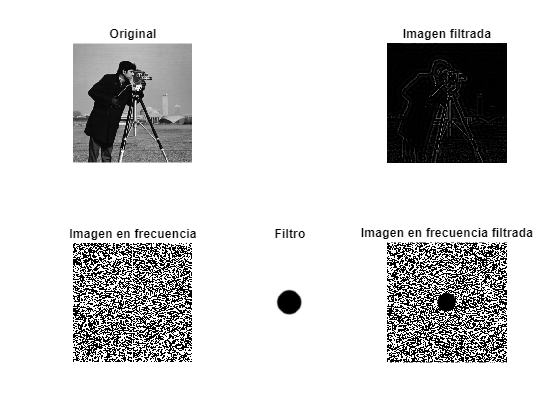

clear all; clc; close all;

% Load and get size of image.
img = imread('cameraman.tif');
imgSize = size(img);


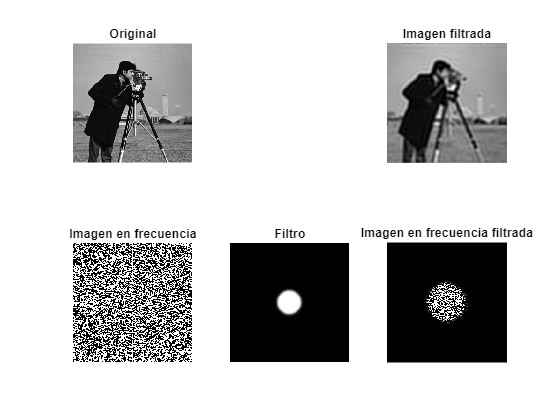

% Get FFT image, generate filter and apply. Get recovered image from frequency Domain.
imgFrec=imfft(img);
filtro = lowpassfilter(imgSize,0.1,10);
img_filtered = imgFrec .* filtro;
imgRecovered=imifft(img_filtered);

% Subplot representation of steps.
figure(2)
subplot(2,3,1)
imshow(img)
title('Original')
subplot(2,3,3)
imshow(uint8(real(imgRecovered)))
title('Imagen filtrada')
subplot(2,3,4)
imshow(real(imgFrec))
title('Imagen en frecuencia')
subplot(2,3,5)
imshow(filtro)
title('Filtro')
subplot(2,3,6)
imshow(real(img_filtered))
title('Imagen en frecuencia filtrada')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **(3) CONCLUSIONES**

- Se ha trabajado en el filtrado en frecuencia usando la transformada rápida de Fourier (*FFT*), un tipo de filtrado de los más populares en el tratamiento digital de imágenes.

- Cuando usamos un filtro paso alto, lo que estamos haciendo es dejar pasar las frecuencias altas de esa imagen, porque nos quedamos con los bordes (de los objetos o escena).

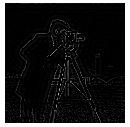

- Cuando usamos un filtro paso bajo, lo que estamos haciendo es dejar pasar las frecuencias bajas de esa imagen, por lo que estamos eliminando los bordes.

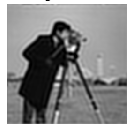

- Al aumentar el grado del filtro (*n*) lo que conseguimos es que el filtro sea más lineal (estricto) y no se expanda mucho más de lo que le estamos indicando con el tamaño del filtro (*CutOffFrec*). Esto se puede ver en la siguiente imagen: